# **Práctica 5: Series de Fourier**

**Integrantes:**

Contreras Avilés Citlali Anahí

Gallegos Ruiz Diana Abigail

Morgado Reséndiz Lisardo René

Ramírez Aniceto Lauro Alexis

Rojas Gómez Ian

**PROFESOR:** Rafael Martínez Martínez

**GRUPO:** 2TV1

## **Problema 1: Ejemplo 6.2**

clear all; clc; close all;

Para este ejemplo, tenemos que el periodo es de $T_0 =2$ y la señal es la siguiente:


$$\[ x(t) = \begin{cases}
 2At & |t| \lt \frac{1}{2} \\
 2A(1-t) & \frac{1}{2} \lt t \lt \frac{3}{2}
\end{cases}
\]$$


y para hacer la representación gráfica de su Serie de Fourier Exponencial, se utilizá la función sfc con sus respectivos parámetros.

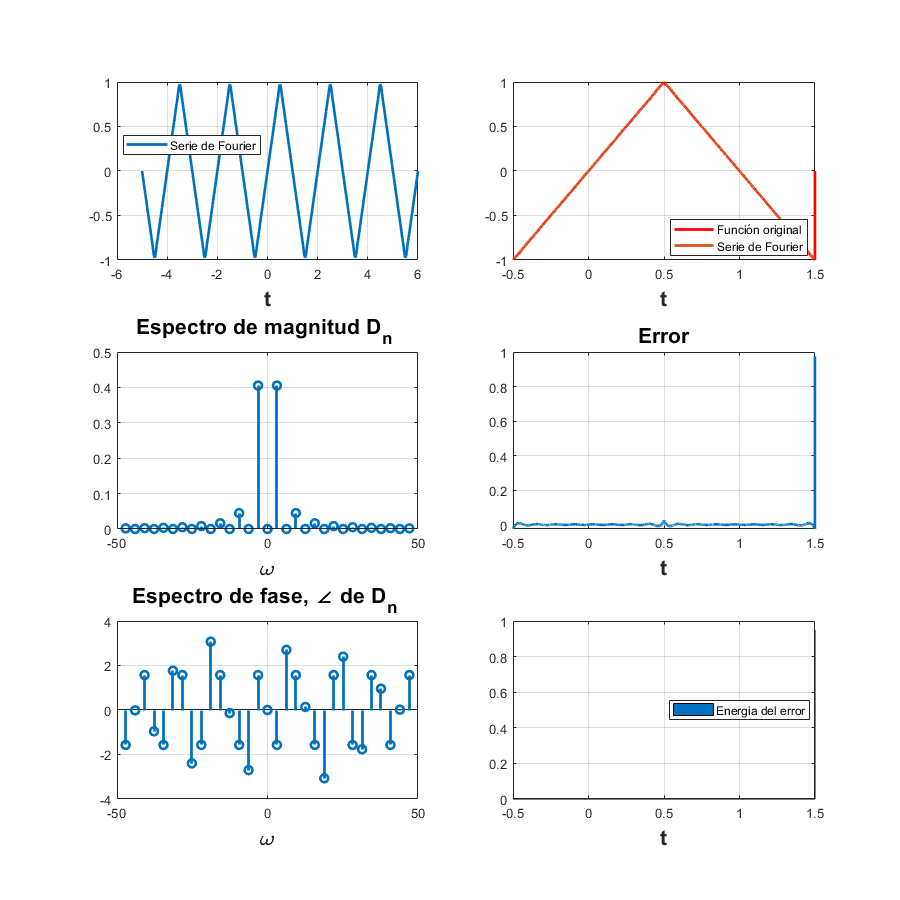

T0 = 2;
w0= 2*pi/T0;
A = 1;
t0 = -1/2;
tf = 3/2;
f = @(t) (2*A*t).*(abs(t) <= 1/2) + 2*A*(1-t).*((1/2 < t) & (t < 3/2));
dn = @(n) integral(@(t) (1/T0).*exp(-n*w0*j*t).*f(t), -1/2, 3/2);
d0 = dn(0);
armo = 15;
a = -5;
b = 6;

sfc(t0,tf,dn,d0,f,armo,a,b);

Después transformamos la Serie de Fourier Exponencial a su Serie de Fourier Trigonométrica Compacta a traves de sus formulas de transformación que son:


$$C_n = 2||D_n|| \\
\phi_n = \angle D_n \\
C_0 = ||D_0| \\
\phi_0| = \angle D_0 \\$$


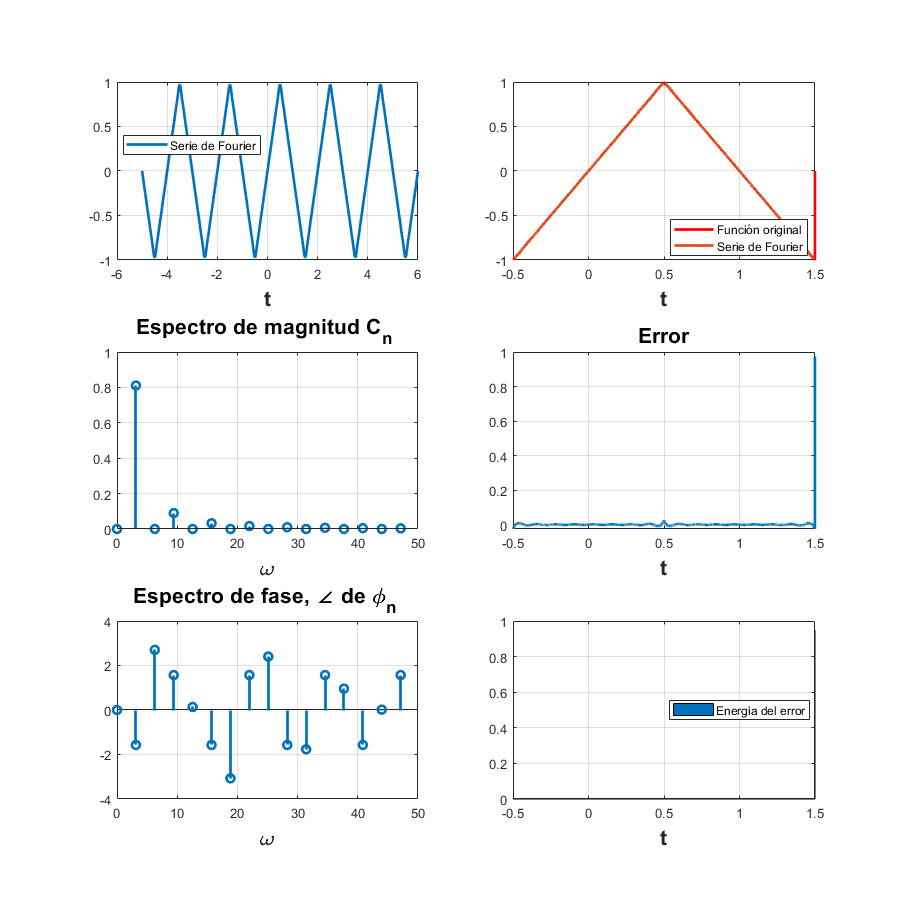

cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(dn(0));
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)

Como se puede observar en ambas Series de Fourier, el error es muy pequeño, tanto que tiende a cero, además de que sus espectros son parecidos, aunque deberían ser igual, el hecho de que se tomen los armónicos negativos en la parte compleja es porque su Serie lo permite.

## Problema 2: Ejemplo 6.4

clear all; clc; close all;

Para este ejemplo, tenemos que el periodo es de $T_0 =2\pi$ y la señal es la siguiente:


$$\[ x(t) = \begin{cases}
 0 & \frac{1}{2}\pi \lt |t|\\
\frac{1}{2} & |t|=\frac{1}{2}\pi\\
1 & |t| \lt \frac{1}{2}\pi \\
\end{cases}
\]$$


y para hacer la representación gráfica de su Serie de Fourier Exponencial, se utilizá la función sfc con sus respectivos parámetros.

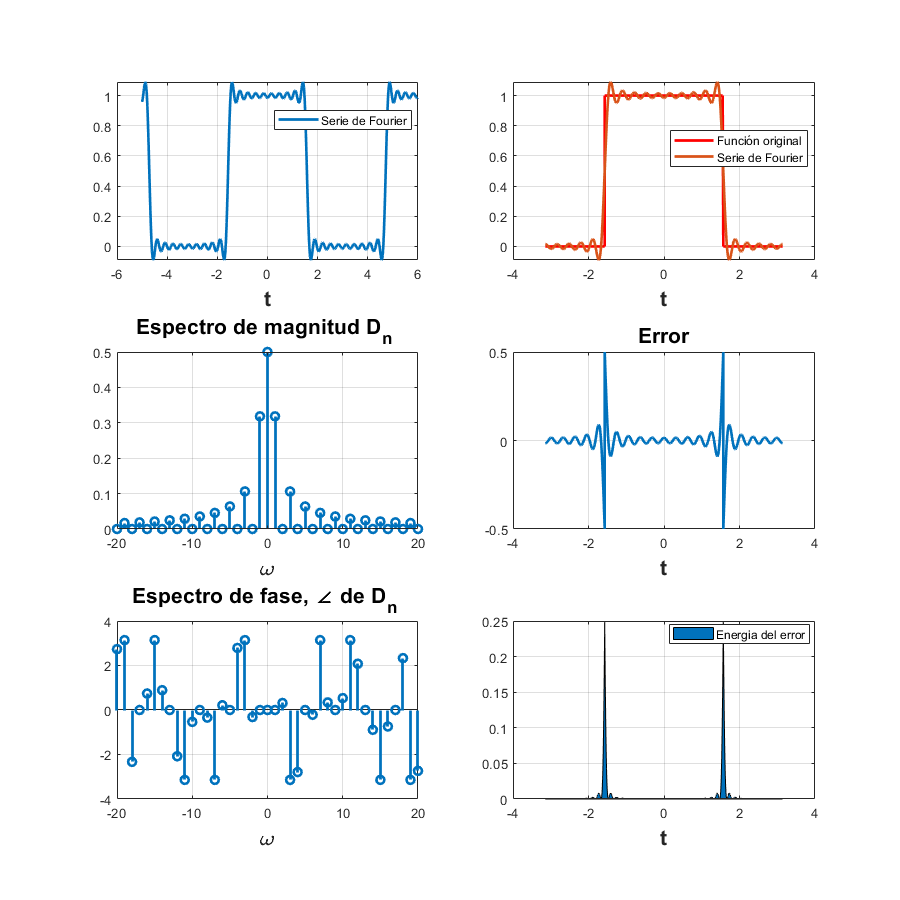

T0 = 2*pi;
w0= 2*pi/T0;
t0 = -pi;
tf = pi;
f = @(t) (0).*(abs(t) > pi/2) + (1/2).*(abs(t) == pi/2) + 1.*(abs(t) < pi/2);
dn = @(n) integral(@(t) (1/T0).*exp(-n*w0*j*t).*f(t), -pi/2, pi/2);
d0 = dn(0);
armo = 20;
a = -5;
b = 6;

sfc(t0,tf,dn,d0,f,armo,a,b);

Después transformamos la Serie de Fourier Exponencial a su Serie de Fourier Trigonométrica Compacta a través de sus fórmulas de transformación que son:


$$C_n = 2||D_n|| \\
\phi_n = \angle D_n \\
C_0 = ||D_0| \\
\phi_0| = \angle D_0 \\$$


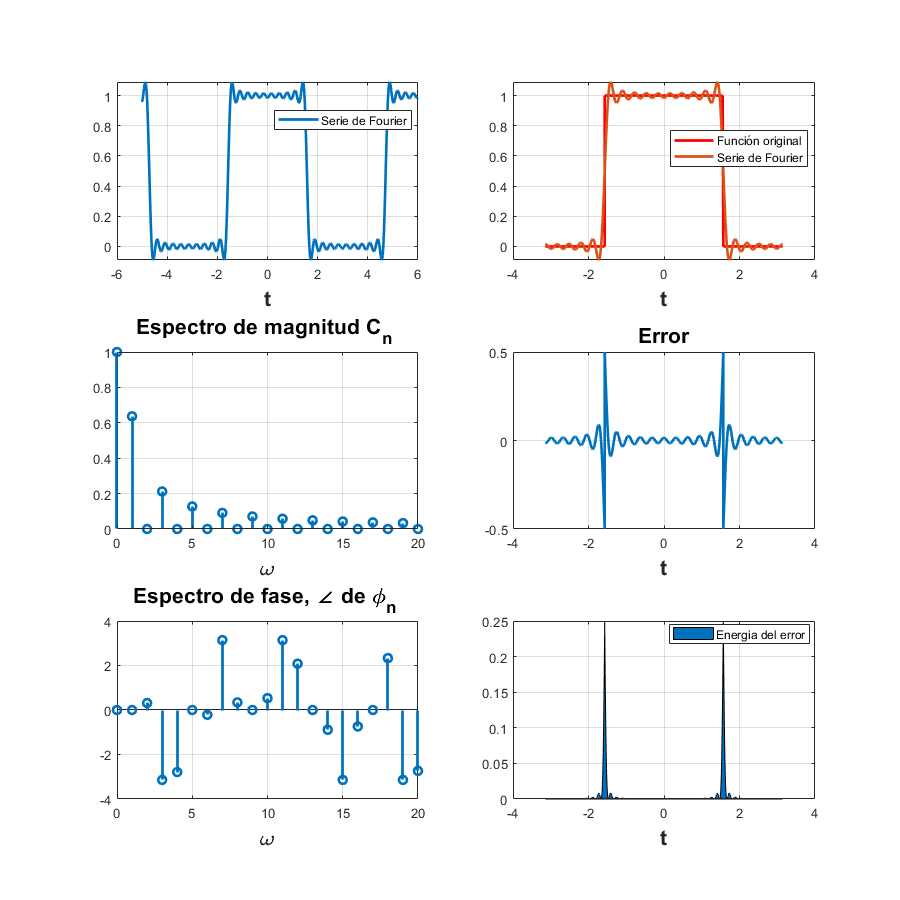

cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(dn(0));
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)

Se puede observar la similitud entre la función y su respectiva Serie de Fourier, en este caso el error se presenta al aproximarse a  -$\frac{\pi }{2}$ y $\frac{\pi }{2}$. Por otro lado, sus espectros son parecidos exceptuando el hecho de que en la exponencial se toman en cuenta los armónicos negativos en la parte compleja porque su Serie lo permite.

## Problema 3 (1)

Encontrar la serie de Fourier compleja para la señal $f(t)=t
$ en el intervalo $\left\lbrack -1,1\right\rbrack$. 

Utilizando la función sfc:

clear all; clc; close all;
syms T
tf=1;
t0=-1;
d0= 1

d0 = 1

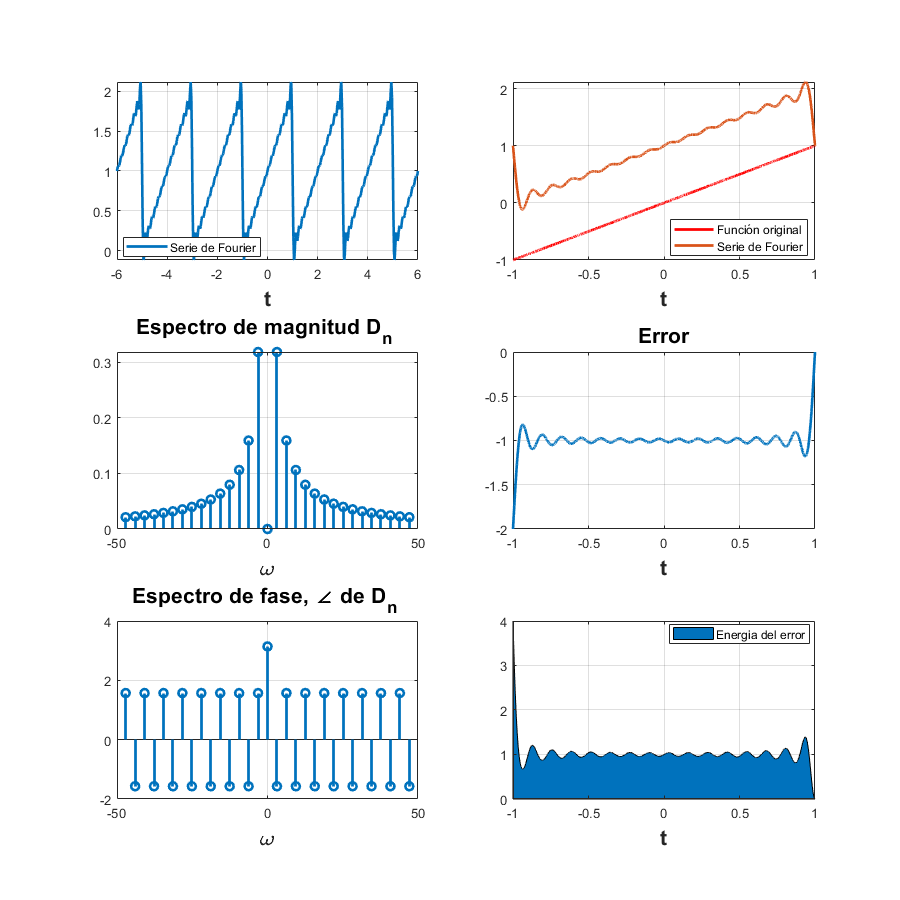

f= @(t) t;
dn= @(n) (1/(tf-t0))*integral( @(t) exp(-n*pi*j*t).*f(t),-1,1);
sf=d0;
armo=15;
a=-6;
b=6;
sfc(t0,tf,dn,d0,f,armo,a,b)

Mediante las fótmulas de transformación , la serie de Fourier trigonométrica  está dada por:

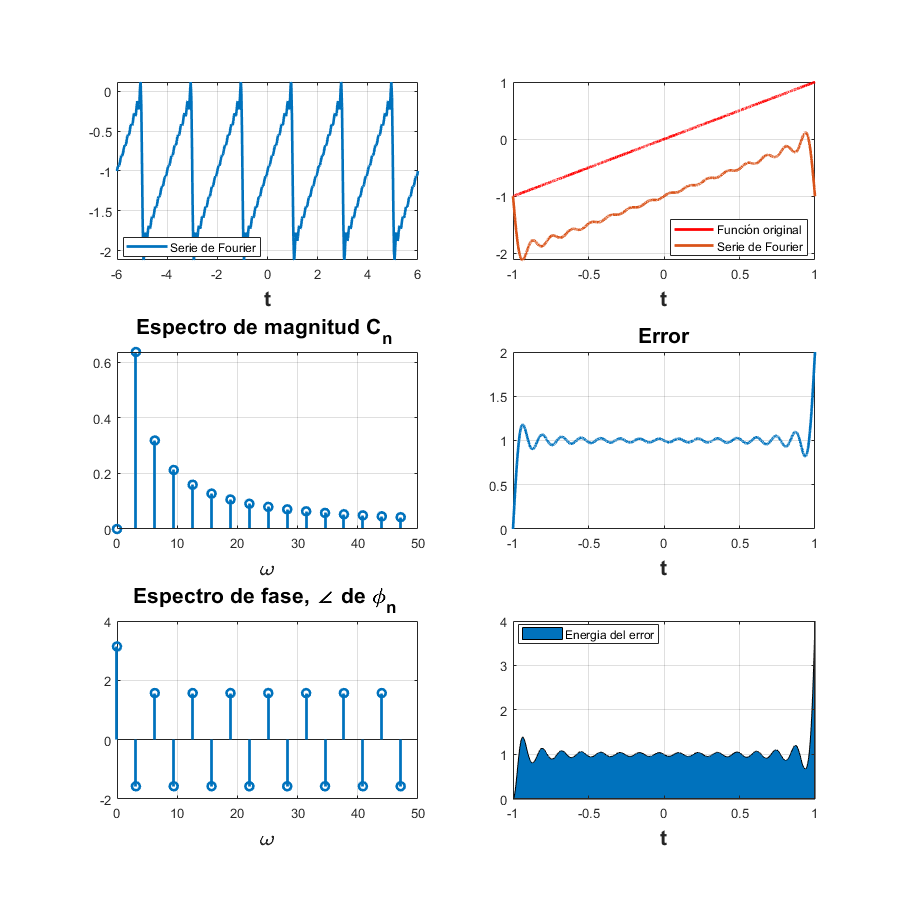

cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(d0);
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)

Debido al fenómeno de Gibbs, el área mostrada en la gráfica del error es más notoria a comparación de los ejemplos.

## Problema 3 (2)

Encontrar la serie de Fourier para la señal $f\left(t\right)=t^2$ en el intervalo $[-2,2]

$.

clear all; clc; close all;
fx= @(t) 1;
tf=2;
t0=-2;
f= @(t) t.^2;
dn= @(n) (1/(tf-t0))*integral( @(t) exp(-n*(pi/2)*j*t).*f(t),-2,2);
d0= dn(0);

sf=d0;
t1=t0:0.0001:tf;
armo=15;
a=-15;
b=15;
sfc(t0,tf,dn,d0,f,armo,a,b)

Mediante las fótmulas de transformación , la serie de Fourier trigonométrica  está dada por:

cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(d0);
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)

## **Problema 4: PR10 - Problema 1 con a=2**

clear all; close all;
syms a t;
T = 2;
w0 = pi;
t0 = -1;
tf = 1;
a_p = 2;

La función de la cuál buscaremos su serie de Fourier es:


$$f\left(t\right)=ae^{-a\left|t\right|}$$


El problema nos da la fórmula de la serie de fourier en su forma exponencial compleja, la cual es:


$$S_f \left(t\right)=\sum_{n=-\infty }^{\infty } \frac{a^2 \left(1-e^{-a} \cos \left(n\pi \right)\right)}{a^2 +n^2 \pi^2 }e^{j\pi \textrm{nt}}$$


De donde sabemos que:

$D_n =\frac{a^2 \left(1-e^{-a} \cos \left(n\pi \right)\right)}{a^2 +n^2 \pi^2 }$ y $w_0 =\pi$

## a) Encontrar el valor de T

Por definición:


$$w_0 =\frac{2\pi }{T}$$


Por lo que, despejando y sustituyendo $w_0$


$$T=2$$


## b) Encontrar el valor promedio de la función

Usaremos la fórmula:


$$\textrm{Vp}\left(f\right)=\frac{1}{T}\int_{<T>} f\left(t\right)\textrm{dt}$$


Vp =@(t) (1/T).*int(a.*exp(-a.*abs(t)),t,[-1 1]);
Vp(t)

$$ans = 1-{\mathrm{e}}^{-a}$$

Por lo tanto, el valor promedio de la función es:


$$\textrm{Vp}\left(f\right)=1-e^{-a}$$


## c) Encontrar el valor de A

La componente f(t) en ciertas frecuencias se puede expresar como $\textrm{Acos}\left(3\pi t\right)$. Determine el valor de A

Igualamos el Dn a el valor dado:

$D_n =\frac{a^2 \left(1-e^{-a} \cos \left(n\pi \right)\right)}{a^2 +n^2 \pi^2 }$= $\textrm{Acos}\left(3\pi t\right)$

Despejamos A y obtenemos el valor requerido:


$$A=\frac{\left(1-e^{-a} \right)}{\left(1+\frac{9}{\textrm{a²}}\pi ²\right)}\ldotp \frac{1}{\textrm{cos³}\left(\pi e\right)}$$


## d) Cálculo y gráficas de series de fourier en ambas formas

La serie de fourier exponencial compleja graficada es:

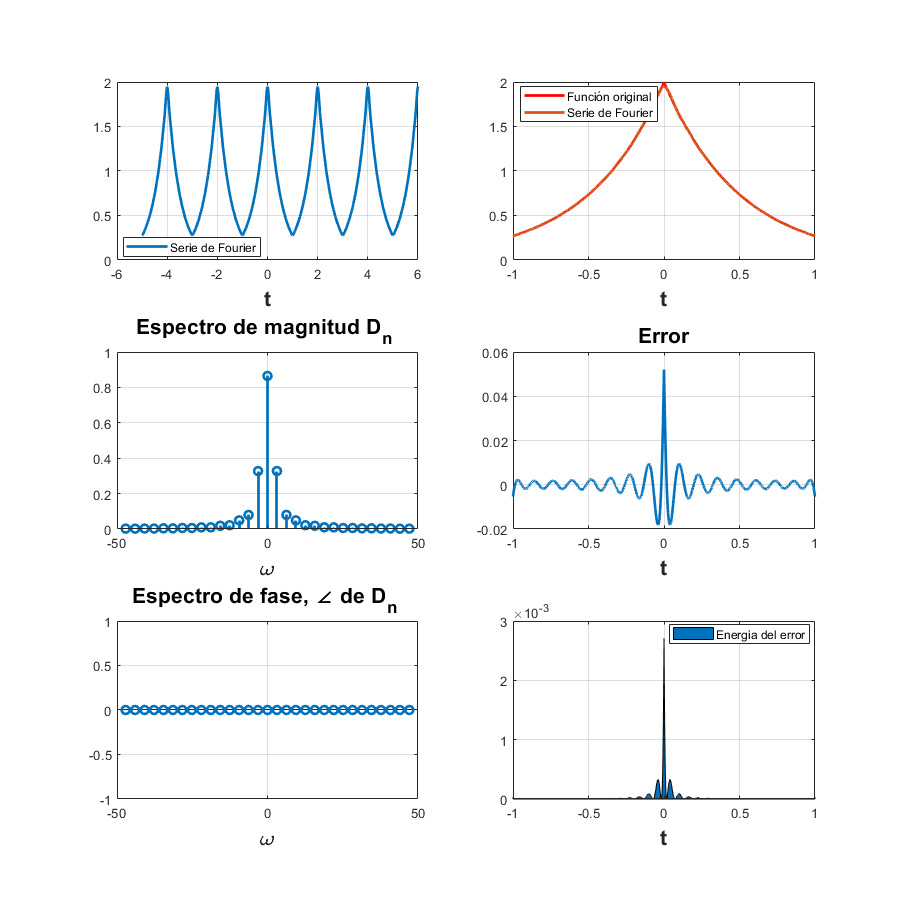

f = @(t) a_p.*exp(-a_p.*abs(t));
dn = @(n) ((a_p.^2).*(1-(exp(-a_p).*cos(n.*pi))))/((a_p.^2)+((n.^2).*(pi.^2)));
d0 = dn(0);

armo = 15;
a = -5;
b = 6;

sfc(t0,tf,dn,d0,f,armo,a,b);

Para obtener la serie de fourier trigonométrica compacta usamos las siguientes fórmulas de transformación:


$$C_n = 2||D_n|| \\
\phi_n = \angle D_n \\
C_0 = ||D_0| \\
\phi_0| = \angle D_0 \\$$


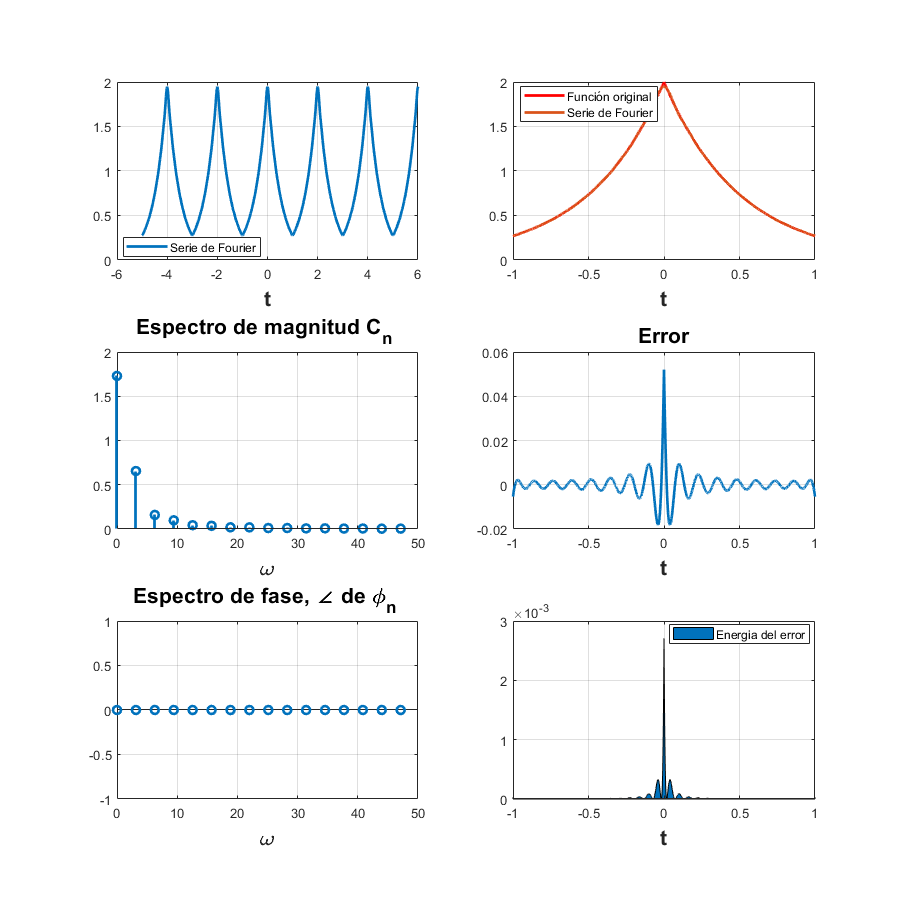

cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(dn(0));
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b);

## **Referencias**

- The MathWorks, (20/12/2020), *integral*, Lugar de Publicación: [https://la.mathworks.com/help/matlab/ref/integral.html](https://la.mathworks.com/help/matlab/ref/integral.html)

- B. P. Lathi, (2018),* LINEAR SYSTEMS AND SIGNALS,* NY, E.U.A, Oxford University Press.

function sfc(t0,tf,dn,d0,f,armo,a,b)
% t0 el valor inicial para calcular la serie
% tf el valor final donde calcular la serie
% dn función de la fórmula de los dn
% f función original
% armo número de armonicos a utilizar en la gráfica
% a, b intevalo para realizar la grafica de la serie

w0=2*pi/(tf-t0);

sf=d0;
t=a:0.0001:b;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t*j)+dn(n)*exp(w0*n*t*j);
end
figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
subplot(3,2,1)
plot(t,sf,'LineWidth',2)
grid on
legend('Serie de Fourier','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)

sf=d0;
t1=t0:0.0001:tf;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t1*j)+dn(n)*exp(w0*n*t1*j);
end

subplot(3,2,2)
plot(t1,f(t1),'r','LineWidth',2)
grid on
hold on
plot(t1,sf,'LineWidth',2)
legend('Función original','Serie de Fourier ','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
nn=-armo:armo;
axis auto

subplot(3,2,4)
e=f(t1)-sf;
plot(t1,e,'LineWidth',2)
title('Error','FontWeight','bold','FontSize',16)
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

subplot(3,2,6)
e=f(t1)-sf;
area(t1,e.^2)
legend('Energia del error','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

absdn=zeros(1,length(nn));
cont=1;
for i =-armo:armo
    if i==0
        absdn(cont)=d0;
    end
    
    absdn(cont)=dn(i);
    cont=cont+1;
end

subplot(3,2,3)
stem(w0*nn,abs(absdn),'LineWidth',2)
title('Espectro de magnitud D_n ','FontWeight','bold','FontSize',16)
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

subplot(3,2,5) % % 
stem(w0*nn,angle(absdn),'LineWidth',2) % % 
title('Espectro de fase, \angle de D_n ','FontWeight','bold','FontSize',16) % % 
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

end

function sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)
% t0 el valor inicial para calcular la serie
% tf el valor final donde calcular la serie
% dn función de la fórmula de los dn
% f función original
% armo número de armonicos a utilizar en la gráfica
% a, b intevalo para realizar la grafica de la serie

w0=2*pi/(tf-t0);

sf=c0*cos(phi0);
t=a:0.0001:b;

for n=1:armo
    sf=sf+cn(n)*cos(n*w0*t + phin(n));
end
figure (2)
hFig = figure(2);
set(hFig, 'Position', [0 0 900 900])
subplot(3,2,1)
plot(t,sf,'LineWidth',2)
grid on
legend('Serie de Fourier','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)

sf=c0*cos(phi0);
t1=t0:0.0001:tf;

for n=1:armo
    sf=sf+cn(n)*cos(n*w0*t1 + phin(n));
end

subplot(3,2,2)
plot(t1,f(t1),'r','LineWidth',2)
grid on
hold on
plot(t1,sf,'LineWidth',2)
legend('Función original','Serie de Fourier ','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
nn= 0:armo;
axis auto

subplot(3,2,4)
e=f(t1)-sf;
plot(t1,e,'LineWidth',2)
title('Error','FontWeight','bold','FontSize',16)
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

subplot(3,2,6)
e=f(t1)-sf;
area(t1,e.^2)
legend('Energia del error','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

abscn=zeros(1,length(nn));
cont=1;
for i =0:armo
    if i==0
        abscn(cont)=c0;
    end
    
    abscn(cont)=cn(i);
    cont=cont+1;
end

subplot(3,2,3)
stem(w0*nn,abs(abscn),'LineWidth',2)
title('Espectro de magnitud C_n ','FontWeight','bold','FontSize',16)
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

angphin=zeros(1,length(nn));
cont=1;
for i =0:armo
    if i==0
        angphin(cont)=phi0;
    end
    
    angphin(cont)=phin(i);
    cont=cont+1;
end

subplot(3,2,5) % % 
stem(w0*nn, angphin,'LineWidth',2) % % 
title('Espectro de fase, \angle de \phi_n ','FontWeight','bold','FontSize',16) % % 
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

end